**Data**

x = [10 20 30 40 50 60 70 80]';
y = [25 70 380 550 610 1220 830 1450]';

**Plot data**

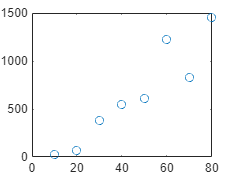

plot(x,y,'o')

**Create Z matrix**

z = [ones(8,1) x x.^2]

z =            1          10         100
           1          20         400
           1          30         900
           1          40        1600
           1          50        2500
           1          60        3600
           1          70        4900
           1          80        6400


**Solve for unknown parameters  a  **

a = (z'*z) \ (z'*y)

a =  -178.4821
   16.1220
    0.0372


**Plot data and the best fitted curve**

xx = 10 : 0.1 : 80

xx =    10.0000   10.1000   10.2000   10.3000   10.4000   10.5000   10.6000   10.7000   10.8000   10.9000   11.0000   11.1000   11.2000   11.3000   11.4000   11.5000   11.6000   11.7000   11.8000   11.9000   12.0000   12.1000   12.2000   12.3000   12.4000   12.5000   12.6000   12.7000   12.8000   12.9000   13.0000   13.1000   13.2000   13.3000   13.4000   13.5000   13.6000   13.7000   13.8000   13.9000   14.0000   14.1000   14.2000   14.3000   14.4000   14.5000   14.6000   14.7000   14.8000   14.9000



yy = a(1) + a(2).*xx + a(3).*xx.*xx

yy = 1.0e+03 *

   -0.0135   -0.0119   -0.0102   -0.0085   -0.0068   -0.0051   -0.0034   -0.0017   -0.0000    0.0017    0.0034    0.0051    0.0068    0.0084    0.0101    0.0118    0.0135    0.0152    0.0169    0.0186    0.0203    0.0220    0.0237    0.0254    0.0272    0.0289    0.0306    0.0323    0.0340    0.0357    0.0374    0.0391    0.0408    0.0425    0.0442    0.0459    0.0477    0.0494    0.0511    0.0528    0.0545    0.0562    0.0580    0.0597    0.0614    0.0631    0.0648    0.0666    0.0683    0.0700


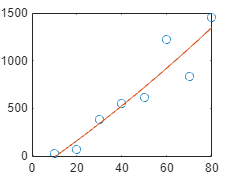


plot(x,y,'o',xx,yy,'-')

**Compute  Sr  (the sum of the squares of the residuals between the best-fit curve and the data)**

Sr = sum((y-z*a).^2)

Sr = 2.1379e+05

**Compute  St   (the sum of the squares of the residuals between the data points and the mean)**

St = sum((y-mean(y)).^2)

St = 1.8083e+06

**Compute  r2  (the coefficient of determination)**

r2 = 1 - Sr/St

r2 = 0.8818

**Compute  syx  (the standard error of the estimate)  **


syx = sqrt(Sr/(length(x)-length(a)))

syx = 206.7815

**Predict the value of y for the given x**

xtest = 45;
predict_y = a(1) + a(2).*xtest + a(3).*xtest.*xtest

predict_y = 622.3438